# 训练DDPG智能体，平衡倒立摆

训练DDPG（Deep Deterministic Policy Gradient）智能体，平衡倒立摆。

同济子豪兄

2022-11-26

## 参考资料

MATLAB深入浅出强化学习 – 从零起步玩转倒立摆：https://www.bilibili.com/video/BV1xf4y1i73L?p=13

[https://ww2.mathworks.cn/help/reinforcement-learning/ug/ddpg-agents.html](https://ww2.mathworks.cn/help/reinforcement-learning/ug/ddpg-agents.html)

[https://ww2.mathworks.cn/help/reinforcement-learning/ug/train-ddpg-agent-to-balance-double-integrator-system.html](https://ww2.mathworks.cn/help/reinforcement-learning/ug/train-ddpg-agent-to-balance-double-integrator-system.html)

[https://ww2.mathworks.cn/help/reinforcement-learning/ug/create-predefined-simulink-environments.html](https://ww2.mathworks.cn/help/reinforcement-learning/ug/create-predefined-simulink-environments.html)

## 构建环境和倒立摆 Simscape 物理模型

在Simulink中创建环境，在Simscape Multibody中创建物理模型

open_system('rlCartPoleSimscapeModel')

## 环境模型

- $\theta_t$ 倒立摆偏转的角度，竖直向上为0，竖直向下为π

- 动作值（Action）：施加给滑块的力，-15N至15N

- 观测值（Observation）：1.滑块的坐标 2.滑块的速度 3.倒立摆偏转角度sin值 4.倒立摆偏转角度cos值 5.倒立摆偏转角速度

- 如果滑块滑动至距起点3.5m外，则终止该episode

- $r_t$ 每一时刻的奖励函数值

## 奖励函数


$${\mathit{\mathbf{r}}}_{\mathit{\mathbf{t}}} =\;-0\ldotp 1\left(5{\theta_{\mathit{\mathbf{t}}} }^2 \;+{x_{\mathit{\mathbf{t}}} }^2 \;+\;0\ldotp 05u_{t-1}^2 \right)-100B$$


- $\theta_t$ 倒立摆偏转的角度，竖直向上为0，竖直向下为π

- $x_t$ 滑块距离中点的距离

- $u_{t-1}$ 上一时刻的电机扭矩

- $B$ 非1即0，表示滑块是否滑出指定范围

## 创建预定义的 Environment Interface

env = rlPredefinedEnv('CartPoleSimscapeModel-Continuous')

env = <a href=""matlab: help rl.env.SimulinkEnvWithAgent"">SimulinkEnvWithAgent</a> with properties:

           Model : rlCartPoleSimscapeModel
      AgentBlock : rlCartPoleSimscapeModel/RL Agent
        ResetFcn : []
  UseFastRestart : on


The interface has a continuous action space where the agent can apply possible torque values from –15 to 15 N to the pole.

从environment interface中，获取观测信息和动作信息

obsInfo = getObservationInfo(env);
numObservations = obsInfo.Dimension(1);
actInfo = getActionInfo(env);

## 时间

Ts = 0.02; % 智能体每一次采样、决策的时间（秒）
Tf = 25;   % 模拟一个episode的最长时间（秒）

## 随机数种子

rng(0)

## 创建Actor神经网络

Actor神经网络：输入观测值，输出动作值。

actorNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(128,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(200,'Name','ActorFC2')
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(1,'Name','ActorFC3')
    tanhLayer('Name','ActorTanh1')
    scalingLayer('Name','ActorScaling','Scale',max(actInfo.UpperLimit))];
actorNetwork = dlnetwork(actorNetwork);

actorOptions = rlOptimizerOptions('LearnRate',5e-04,'GradientThreshold',1); % actor神经网络训练超参数

actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);       % actor representation

## 可视化Actor神经网络

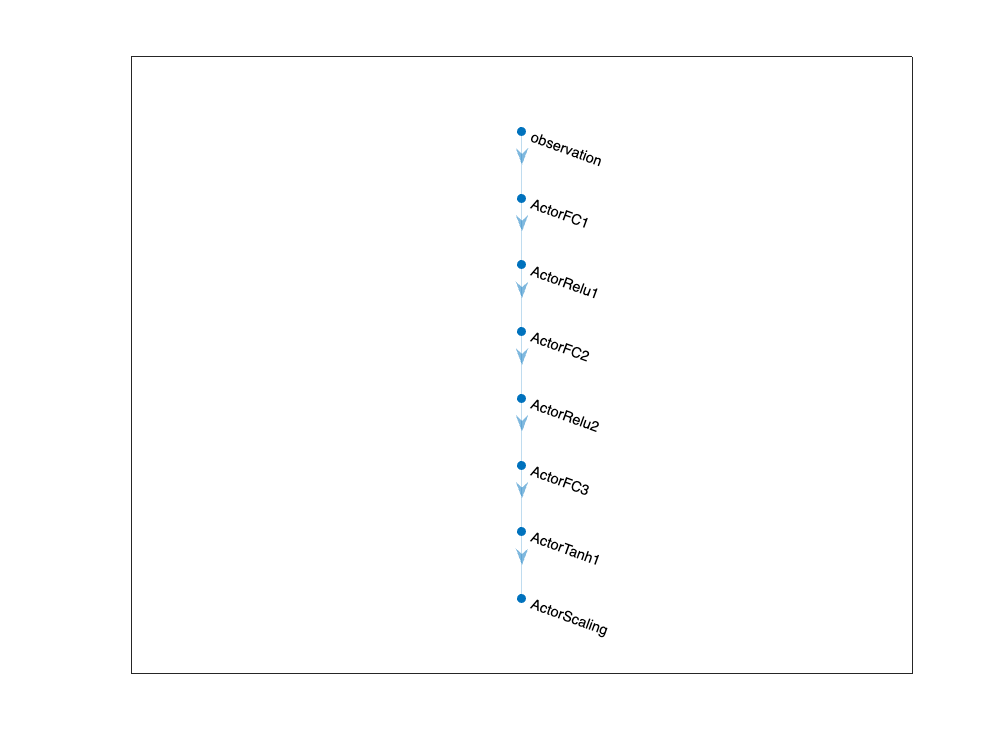

figure
plot(layerGraph(actorNetwork))

## 创建Critic神经网络

Critic神经网络：输入观测值和动作值，输出Q值

文档：https://ww2.mathworks.cn/help/reinforcement-learning/ug/create-policy-and-value-function-representations.html

statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(128,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(200,'Name','CriticStateFC2')];

actionPath = [
    featureInputLayer(1,'Normalization','none','Name','action')
    fullyConnectedLayer(200,'Name','CriticActionFC1','BiasLearnRateFactor',0)];

commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
    
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');
criticNetwork = dlnetwork(criticNetwork);

criticOptions = rlOptimizerOptions('LearnRate',1e-03,'GradientThreshold',1);  % critic神经网络训练超参数

critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,'ObservationInputNames','observation','ActionInputNames','action'); % critic representation 文档：https://ww2.mathworks.cn/help/reinforcement-learning/ref/rlqvaluefunction.html

## 可视化Critic神经网络

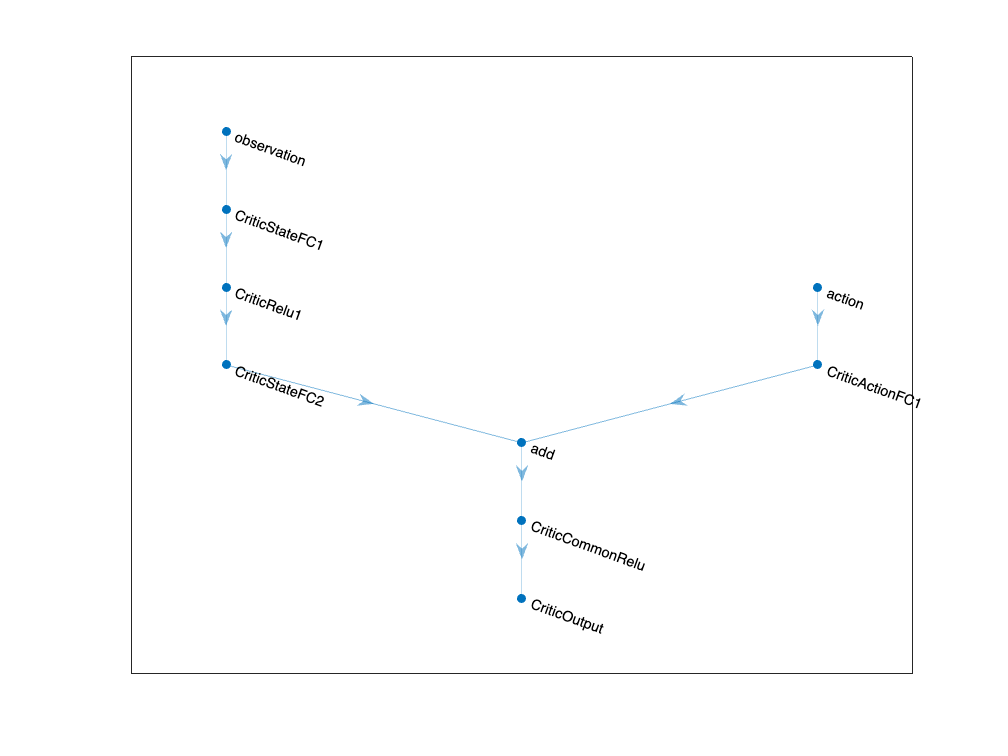

figure
plot(layerGraph(criticNetwork))

## 创建DDPG智能体

指定训练超参数

文档：https://ww2.mathworks.cn/help/reinforcement-learning/ref/rlddpgagentoptions.html?requestedDomain=cn

agentOptions = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'ActorOptimizerOptions',actorOptions,...
    'CriticOptimizerOptions',criticOptions,...
    'ExperienceBufferLength',1e6,...
    'MiniBatchSize',128);
agentOptions.NoiseOptions.Variance = 0.4;
agentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

使用representation, critic representation, agent options，创建智能体

文档：https://ww2.mathworks.cn/help/reinforcement-learning/ref/rlddpgagent.html?requestedDomain=cn

agent = rlDDPGAgent(actor,critic,agentOptions);

## 载入预训练模型，模拟一个episode

文档：https://ww2.mathworks.cn/help/reinforcement-learning/ref/rlsimulationoptions.html

% load('SimscapeCartPoleDDPG.mat','agent')
% simOptions = rlSimulationOptions('MaxSteps',16000);
% experience = sim(env,agent,simOptions);
% bdclose('rlCartPoleSimscapeModel')

## 从头训练

### 指定训练参数

文档：https://ww2.mathworks.cn/help/reinforcement-learning/ref/rltrainingoptions.html

trainingOptions = rlTrainingOptions(...
    'MaxEpisodes',200,...                        % 最大训练episode个数
    'MaxStepsPerEpisode',ceil(Tf/Ts),...         % 每个episode最大训练时刻数
    'ScoreAveragingWindowLength',5,...           % 滑动平均窗口长度
    'Verbose',false,...                          % 是否在命令行界面输出结果
    'Plots','training-progress',...              % 训练过程图标名称
    'StopTrainingCriteria','AverageReward',...   % 训练完成的判定依据：滑动平均累计奖励
    'StopTrainingValue',-350,...                 % 当判定依据大于该值时，停止训练
    'SaveAgentCriteria','EpisodeReward',...      % 保存模型的判定依据
    'SaveAgentValue',-380);                      % 当判定依据大于该值时，保存模型

### 训练（在CPU笔记本电脑上，大约需要一小时）

trainingStats = train(agent,env,trainingOptions);